# Exercise 7

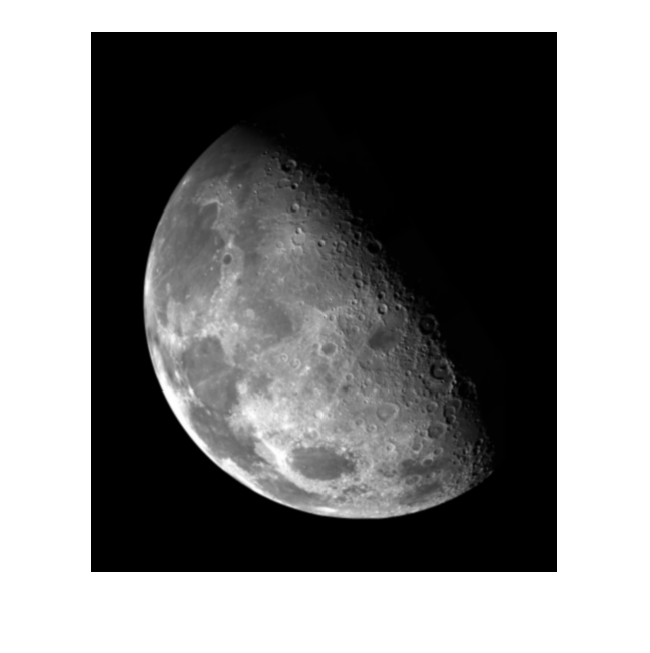

IM= imread('moon.tif');
imshow(IM);



moonbin=imbinarize(IM,'adaptive','ForegroundPolarity','dark','Sensitivity',0.5);
% stats = regionprops('table', moonbin,'Centroid', 'MajorAxisLength','MinorAxisLength');
% 
% centers = stats.Centroid;
% diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
% radii = diameters/2;

Rmin=5; %%radius range
Rmax=300

Rmax = 300


imshow(1-moonbin)
[centers, radii] = imfindcircles(1-moonbin,[Rmin Rmax],'ObjectPolarity','bright'); %%find ci

length(centers)

ans = 5

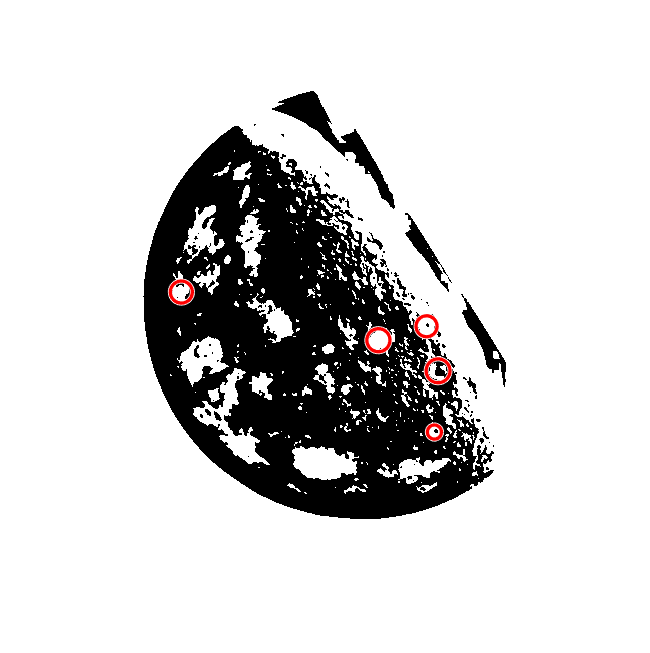



hold on
viscircles(centers,radii);
hold off


%see also previous commit